% Load data
data = csvread('/Users/anika/Desktop/ABL-Web-App/NHANES_analysis/data_all_SI.csv');
Y = data(:, 1);
X = data(:, 2:end);

% Split the data into training and testing sets (80:20)
cv = cvpartition(size(X, 1), 'HoldOut', 0.2);
idx_train = cv.training;
idx_test = cv.test;
 
% Training set
X_train = X(idx_train, :);
Y_train = Y(idx_train, :);

% Testing set
X_test = X(idx_test, :);
Y_test = Y(idx_test, :);

% Define the neural network architecture
hiddenLayerSize = 10; % Number of neurons in the hidden layer
net = feedforwardnet(hiddenLayerSize);

% Transfer functions
net.layers{1}.transferFcn = 'tansig'; % Hyperbolic tangent sigmoid for hidden layer
net.layers{2}.transferFcn = 'purelin'; % Linear transfer function for output layer

% Training function and its parameters
net.trainFcn = 'trainlm'; % Levenberg-Marquardt backpropagation
net.trainParam.min_grad = 1e-10; % Minimum performance gradient
net.trainParam.mu = 1e-3; % Initial mu
net.trainParam.mu_dec = 0.1; % Mu decrease factor
net.trainParam.mu_inc = 10; % Mu increase factor
net.trainParam.mu_max = 1e10; % Maximum mu

% Train the neural network
net = train(net, X_train', Y_train');

% Predict on the test data
Y_test_pred = net(X_test');

% Calculate accuracy based on the specified tolerance
tolerance = 30;
num_correct_predictions = sum(abs(Y_test - Y_test_pred') <= tolerance)
accuracy = num_correct_predictions / numel(Y_test) * 100;

fprintf('Accuracy: %.2f%%\n', accuracy);

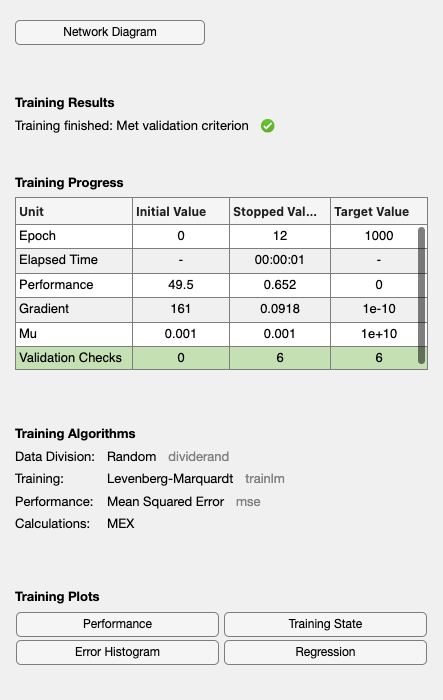

% Define the number of Monte Carlo iterations
num_iterations = 100; % Adjust the number of iterations as needed

% Define arrays to store accuracy for each iteration
total_accuracy_sum = 0;

for i = 1:num_iterations
    % Split the data into training and testing sets (80:20)
    cv = cvpartition(size(X, 1), 'HoldOut', 0.2);
    idx_train = cv.training;
    idx_test = cv.test;

    % Training set
    X_train = X(idx_train, :);
    Y_train = Y(idx_train, :);

    % Testing set
    X_test = X(idx_test, :);
    Y_test = Y(idx_test, :);

    % Define the neural network architecture
    hiddenLayerSize = 30; % Number of neurons in the hidden layer
    net = feedforwardnet(hiddenLayerSize);

    % Transfer functions
    net.layers{1}.transferFcn = 'tansig'; % Hyperbolic tangent sigmoid for hidden layer
    net.layers{2}.transferFcn = 'purelin'; % Linear transfer function for output layer

    % Training function and its parameters
    net.trainFcn = 'trainlm'; % Levenberg-Marquardt backpropagation
    net.trainParam.min_grad = 1e-10; % Minimum performance gradient
    net.trainParam.mu = 1e-3; % Initial mu
    net.trainParam.mu_dec = 0.1; % Mu decrease factor
    net.trainParam.mu_inc = 10; % Mu increase factor
    net.trainParam.mu_max = 1e10; % Maximum mu

    % Train the neural network
    net = train(net, X_train', Y_train');

    % Predict on the test data
    Y_test_pred = net(X_test');
    accuracy_sum = sum(1 - abs(Y_test_pred' - Y_test) ./ Y_test);
    total_accuracy_sum = total_accuracy_sum + accuracy_sum;
end


% Calculate average accuracy over all iterations
average_accuracy = total_accuracy_sum / (100 * numel(Y_test));
fprintf('Average Accuracy: %.6f\n', average_accuracy);

Average Accuracy: 0.720233
